# Esercizio di Robotica Industriale

clear; close all; clc;

% Bracci del robot
global L
L = [0; 0.9; 0.9];

## Triangolo

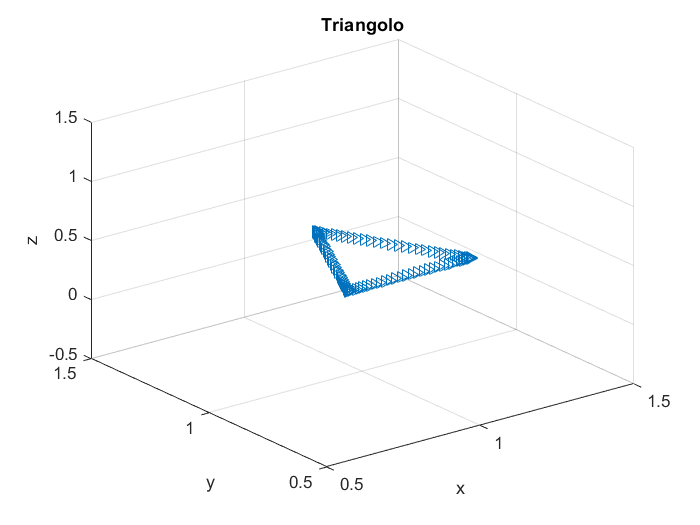

% Vertici del triangolo
P1 = [0.8; 0.8; 0.5];
P2 = [1.2; 0.8; 0.5];
P3 = [1.0; 1.2; 0.5];

% Tempi di esecuzione
T1 = 0; T2 = 13.3333;
T3 = 28.6667; T4 = 40;

% Sigma
DSIGMA = 0.03;
sigma = 0:DSIGMA:1;
N = length(sigma);

% Lambda
lambda = poly3(sigma);
lambda_d = poly3d(sigma);

% Posizione dell'end-effector
global P;

% Percorso P1->P2
for i = 1:N
    % Parametrizzazione del percorso
    P = P1+lambda(i)*(P2-P1);
    % Calcolo della cinematica inversa
    Q = Antropomorfo_Cin_Inv(L, P);
    % Calcolo di J(Q)
    J = Jacobiano_Antropomorfo(L,Q);
    % Risoluzione del sistema di eq. lineari J(Q)*Qd=Pd
    Pd = (P2-P1)*lambda_d(i)/(T2-T1);
    Qd = inv(J)*Pd;
    
    QQ(i,:)=Q; % Variabili di giunto all'istante i
    PP(i,:)=P; % Posizione dell'end effector all'istante i
    QQd(i,:)=Qd; % Velocita' dei giunti all'istante i
end

% Percorso P2->P3
for i = 2:N
    P = P2+lambda(i)*(P3-P2);
    Q = Antropomorfo_Cin_Inv(L, P);
    J = Jacobiano_Antropomorfo(L,Q);
    Pd = (P3-P2)*lambda_d(i)/(T3-T2);
    Qd = inv(J)*Pd;
    
    QQ(i+N-1,:)=Q;
    PP(i+N-1,:)=P;
    QQd(i+N-1,:)=Qd;
end

% Percorso P3->P1
for i = 2:N
    P = P3+lambda(i)*(P1-P3);
    Q = Antropomorfo_Cin_Inv(L, P);
    J = Jacobiano_Antropomorfo(L,Q);
    Pd = (P1-P3)*lambda_d(i)/(T4-T3);
    Qd = inv(J)*Pd;
    
    QQ(i+2*N-2,:)=Q;
    PP(i+2*N-2,:)=P;
    QQd(i+2*N-2,:)=Qd;
end

% Plot percorso
figure(1);
plot3(PP(:,1),PP(:,2),PP(:,3),'>');
axis([0.5 1.5 0.5 1.5]);
title('Triangolo');
grid;
xlabel('x'); ylabel('y'); zlabel('z');

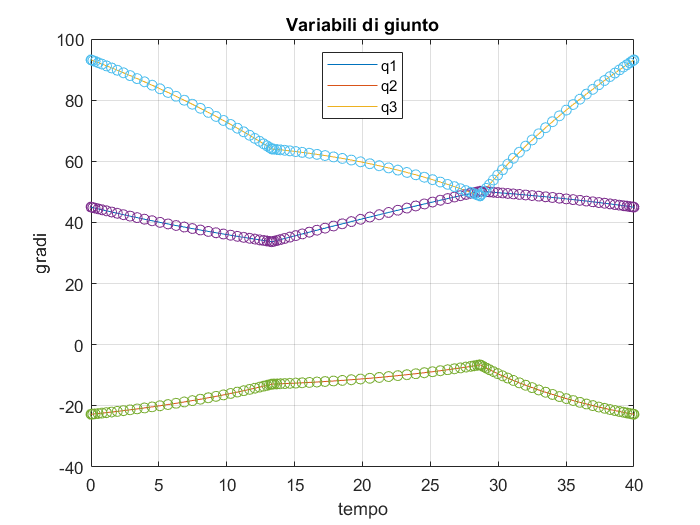

% Plot variabili di giunto
t1 = T1+lambda*(T2-T1);
t2 = T2+lambda*(T3-T2);
t3 = T3+lambda*(T4-T3);
t = [t1 t2(2:N) t3(2:N)];

figure(2);
plot(t,QQ*180/pi);
title('Variabili di giunto');
grid;
hold on;
plot(t,QQ*180/pi,'o');
hold off;
leg = legend('q1', 'q2', 'q3');
leg.Location = 'north';
xlabel('tempo'); ylabel('gradi');

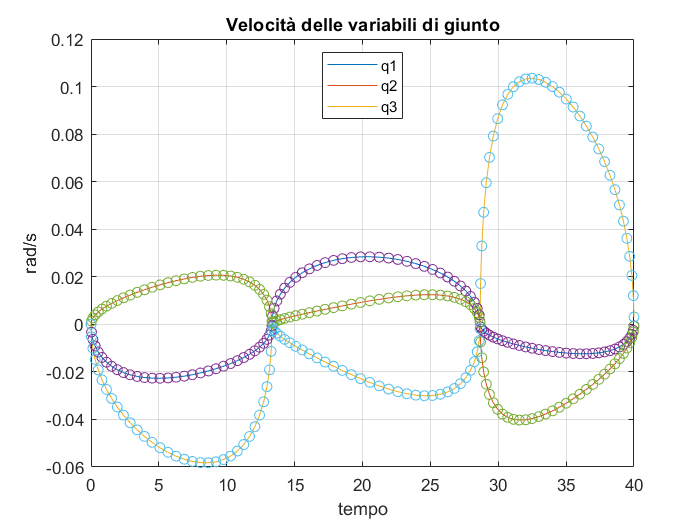

% Plot velocita' delle variabili di giunto
figure(3);
plot(t,QQd);
title('Velocità delle variabili di giunto');
grid;
hold on;
plot(t,QQd,'o');
hold off;
leg = legend('q1', 'q2', 'q3');
leg.Location = 'north';
xlabel('tempo'); ylabel('rad/s');

## Circonferenza

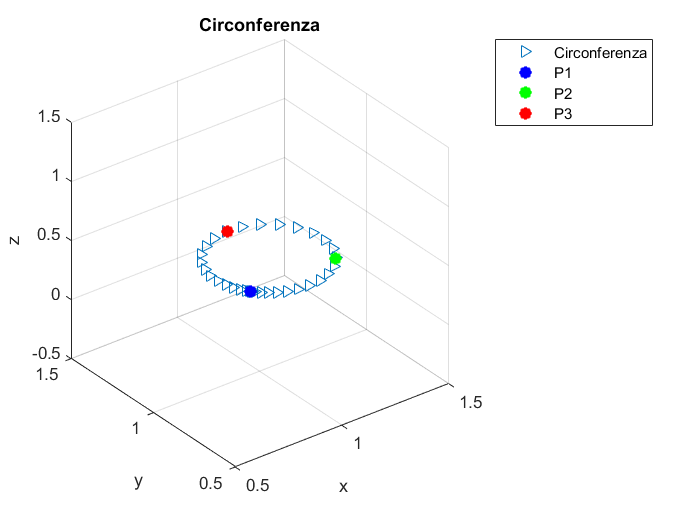

% Circonferenza
PC = [1; 0.95; 0.5];
r = 0.25;

% Theta
theta = 3.8+lambda*2*pi;

% Percorso Circonferenza
for i=1:N
    P = PC+r*[cos(theta(i)); sin(theta(i)); 0];
    Q = Antropomorfo_Cin_Inv(L,P);
    J = Jacobiano_Antropomorfo(L,Q');
    Pd=(r*[-sin(theta(i)), cos(theta(i)), 0]*lambda_d(i)*2*pi)/(T4-T1);
    Qd = inv(J)*Pd';
    
    QQc(i,:)=Q;
    PPc(i,:)=P;
    QQdc(i,:)=Qd;
end

% Plot percorso
figure(4);
plot3(PPc(:,1),PPc(:,2),PPc(:,3),'>');
axis([0.5 1.5 0.5 1.5]);
hold on;
plot3(P1(1), P1(2), P1(3), '*', 'Color','b', 'LineWidth', 5);
plot3(P2(1), P2(2), P2(3), '*', 'Color','g', 'LineWidth', 5);
plot3(P3(1), P3(2), P3(3), '*', 'Color','r', 'LineWidth', 5);
title('Circonferenza');
grid;
xlabel('x'); ylabel('y'); zlabel('z');
legend('Circonferenza', 'P1', 'P2', 'P3');
hold off;

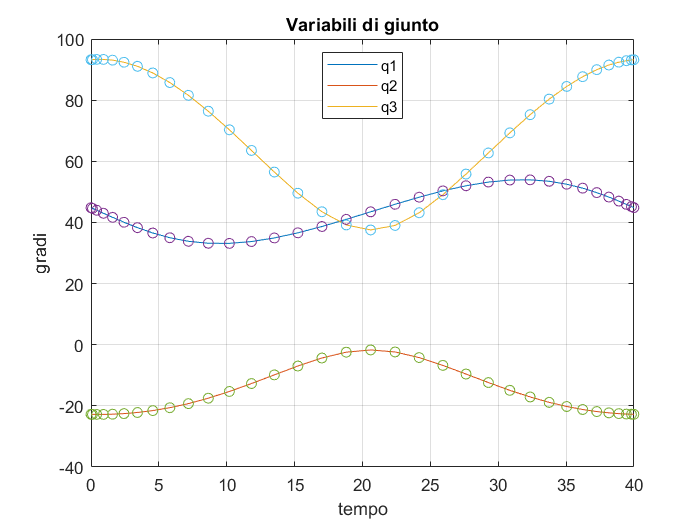

% Plot variabili di giunto
t=T1+lambda*(T4-T1);
figure(5);
plot(t,QQc*180/pi);
title('Variabili di giunto');
grid;
hold on;
plot(t,QQc*180/pi,'o');
hold off;
leg = legend('q1', 'q2', 'q3');
leg.Location = 'north';
xlabel('tempo'); ylabel('gradi');

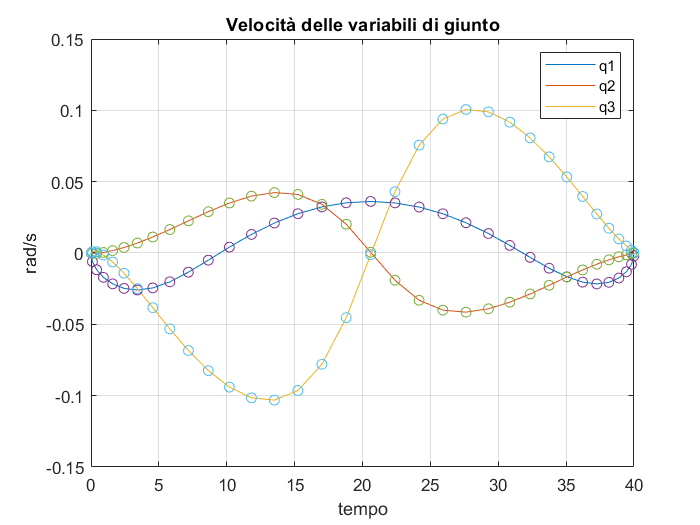

% Plot velocita' delle variabili di giunto
figure(6);
plot(t,QQdc);
title('Velocità delle variabili di giunto');
grid;
hold on;
plot(t,QQdc,'o');
hold off;
legend('q1', 'q2', 'q3');
xlabel('tempo'); ylabel('rad/s');